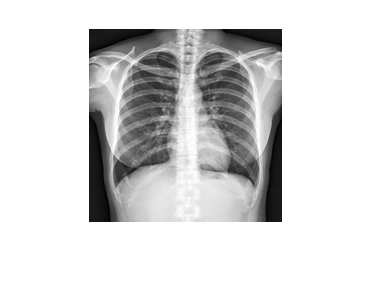

f=imread('radiograph1.jpg');
f=double(f(:,:,1));
f=f/max(max(f));
f=imresize(f,0.15);
figure(1)
imshow(f,[]);

## Thresholding

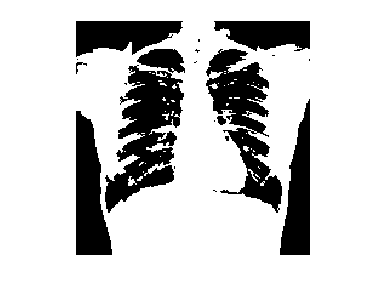

seg1 = f > 0.5;
imshow(seg1,[])

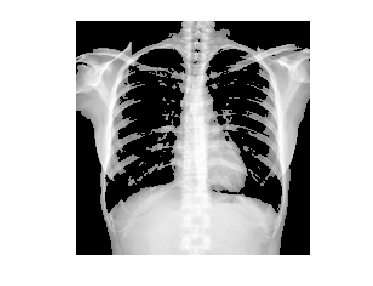

imshow(seg1.*f,[])

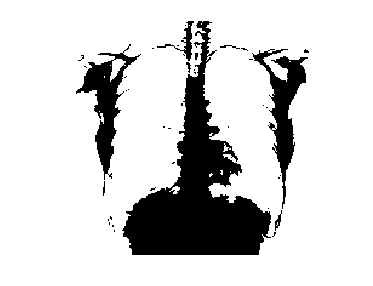

seg1 = f < 0.75;
imshow(seg1,[])

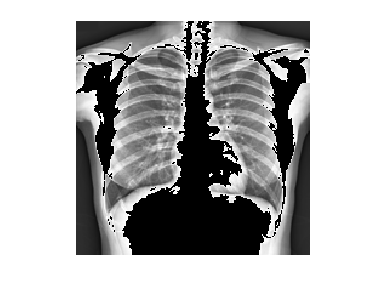

imshow(seg1.*f,[])

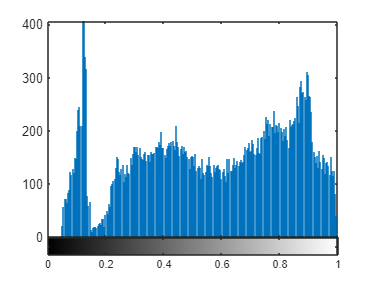


imhist(f)

% Use a third threshold based on the histogram

## Otsu method

thr = graythresh(f)

thr = 0.5490

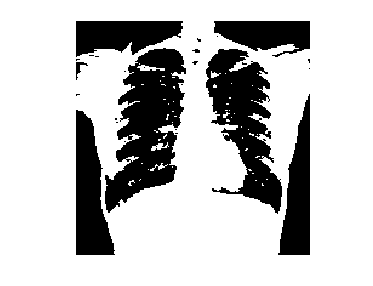

seg1 = f > thr;
imshow(seg1,[])

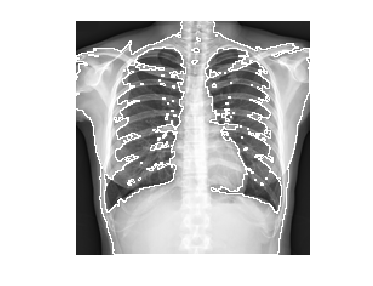

dxp=[0,1;-1,0];
dyp=[1,0;0,-1];
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);


% Compare the otsu provided threshold vs the one you selected in the
% preview step.
% Do you trust the Otsu treshold?
% Select your own image and compute the otsu threshold

## Kmeans segmentation

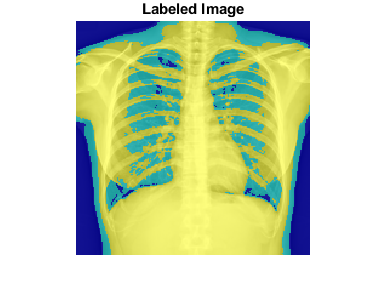

[L,Centers] = imsegkmeans(int8(255*f),3);
B = labeloverlay(f,L);
imshow(B)
title("Labeled Image")

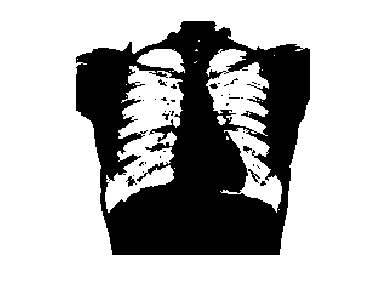

imshow(int8(255*f)<Centers(1),[])

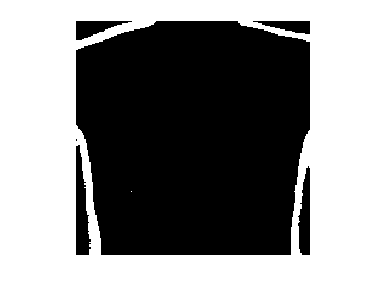

imshow(int8(255*f)<Centers(2),[])

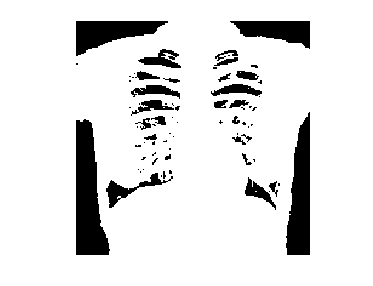

imshow(int8(255*f)>Centers(3),[])

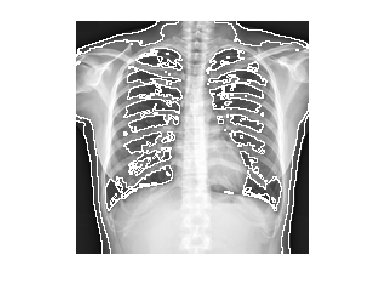

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);


% Do the same procedure but now with 5 centers.
% Is the segmentation better?

## Watershed segmentation

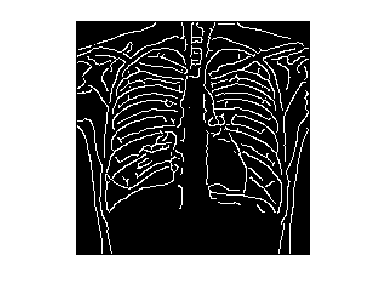

edgeC = edge(f,'Canny');
imshow(edgeC,[])

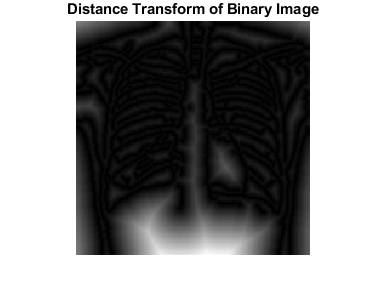

D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')

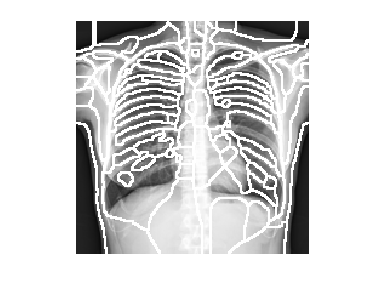

L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);



L(edgeC) = 0;

Display the resulting label matrix as an RGB image.

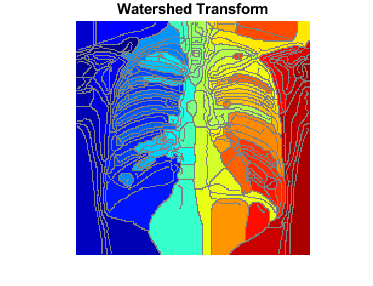

rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')


% provide an alterante segmentation based on a different edge detector